clc;
clear;
amplitude = 1;
titulo = sprintf("Resposta degrau com amplitude %d", amplitude);
tempo = 100;
k = 1; %controlador P

%VÁLVULA
numv = 1;
denv = [1 0];
val = tf(numv, denv)

val =
 
  1
  -
  s
 
Continuous-time transfer function.
Model Properties



%TANQUE
numt = 1;
dent = [1 2];
tanqu = tf(numt, dent)

tanqu =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties



%MAIS UM TANQUE CASCATA COM POLO NULO QUADRÁTICO
numC = 1;
denC = [1 0 0];
tanquC = tf(numC, denC)

tanquC =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties



%REDUÇÃO DE BLOCOS
G1 = series(val, tanqu);
G2 = series(G1, tanquC);
G3 = series(G2, k)

G3 =
 
       1
  -----------
  s^4 + 2 s^3
 
Continuous-time transfer function.
Model Properties


G = feedback(G3, 1)

G =
 
         1
  ---------------
  s^4 + 2 s^3 + 1
 
Continuous-time transfer function.
Model Properties


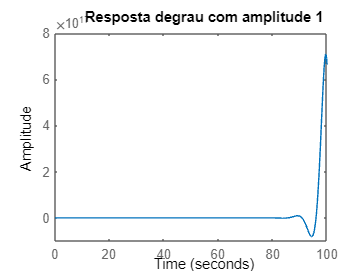


%RESPOSTA DO SISTEMA 1
step(G*amplitude, tempo) %esse número pós virgula é o eixo x
title(titulo);

a = dcgain(G3);
erro = 1/(1+a)

erro = 0

stepinfo(G*amplitude)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


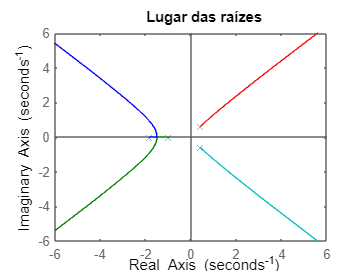

figure;
rlocus(G*amplitude)
title("Lugar das raízes"); %o valor não muda, pois não precisa depende do STEP